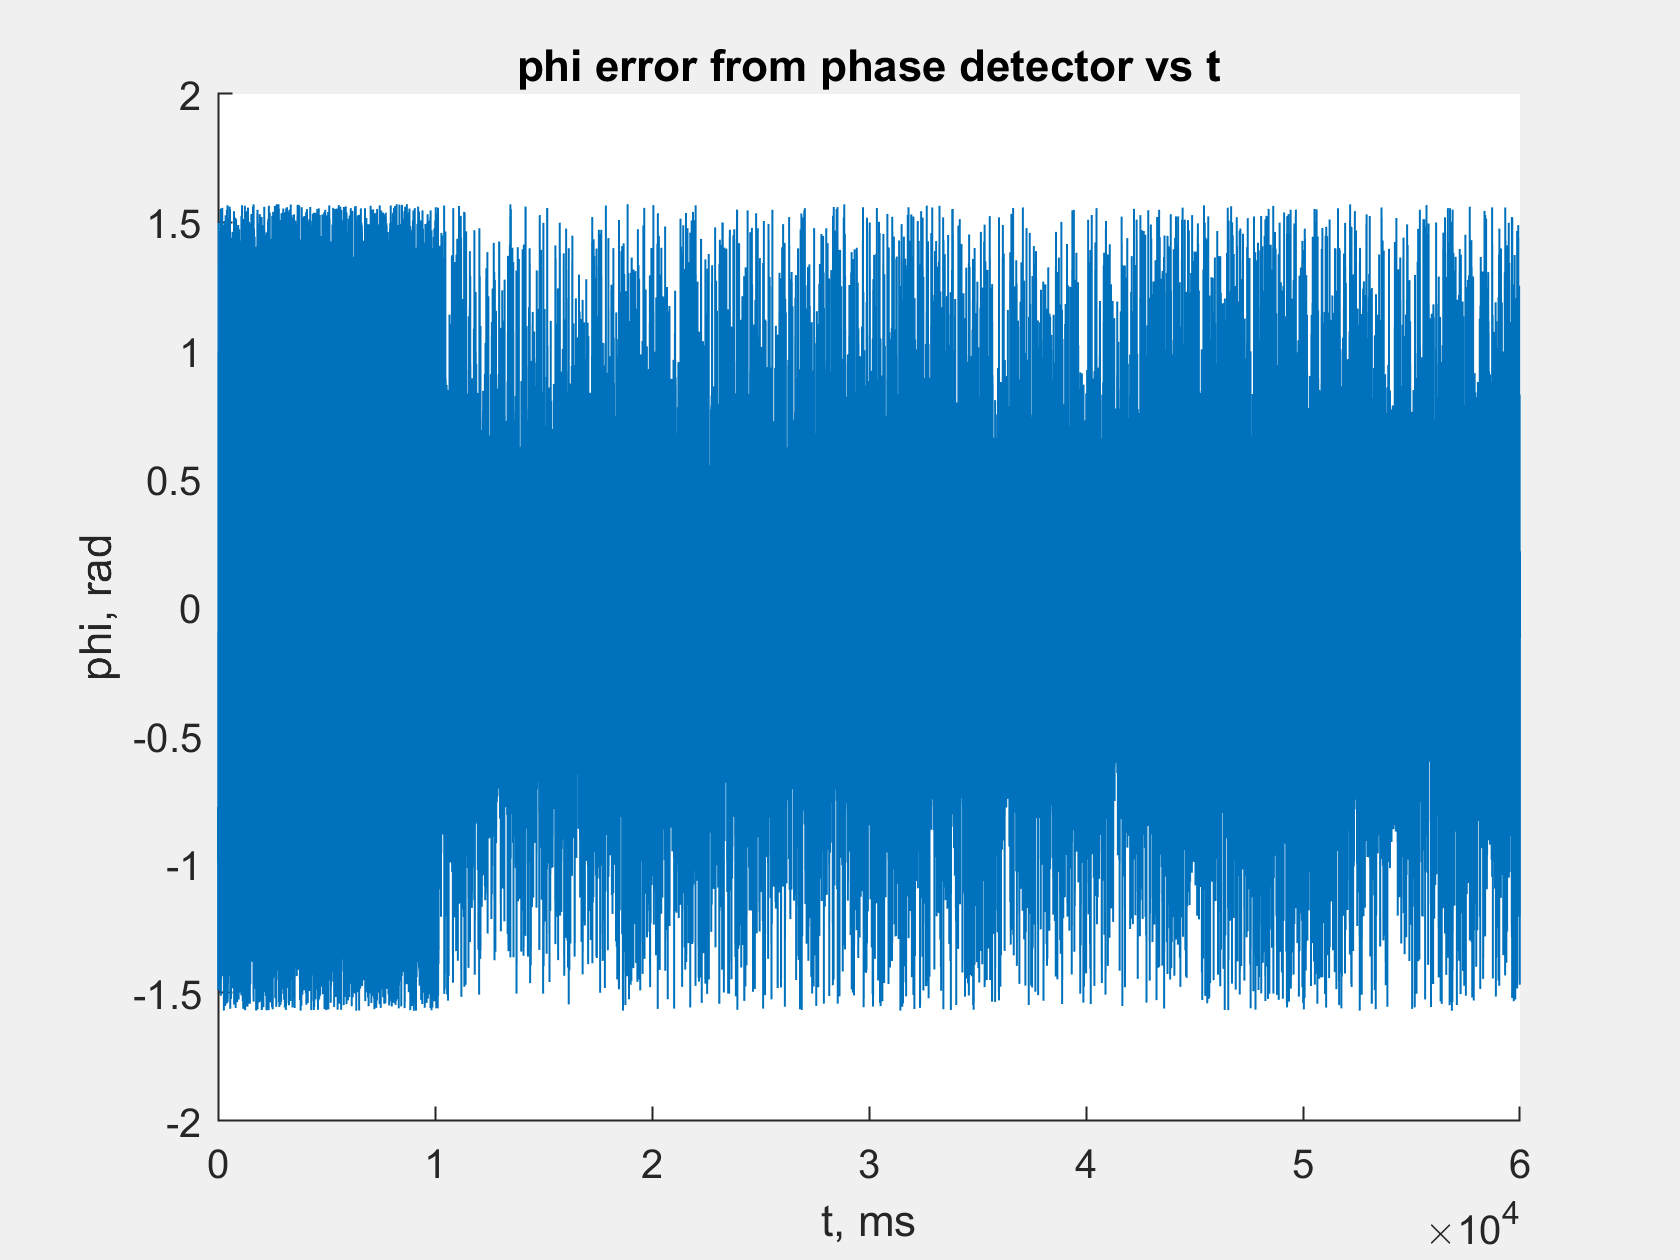

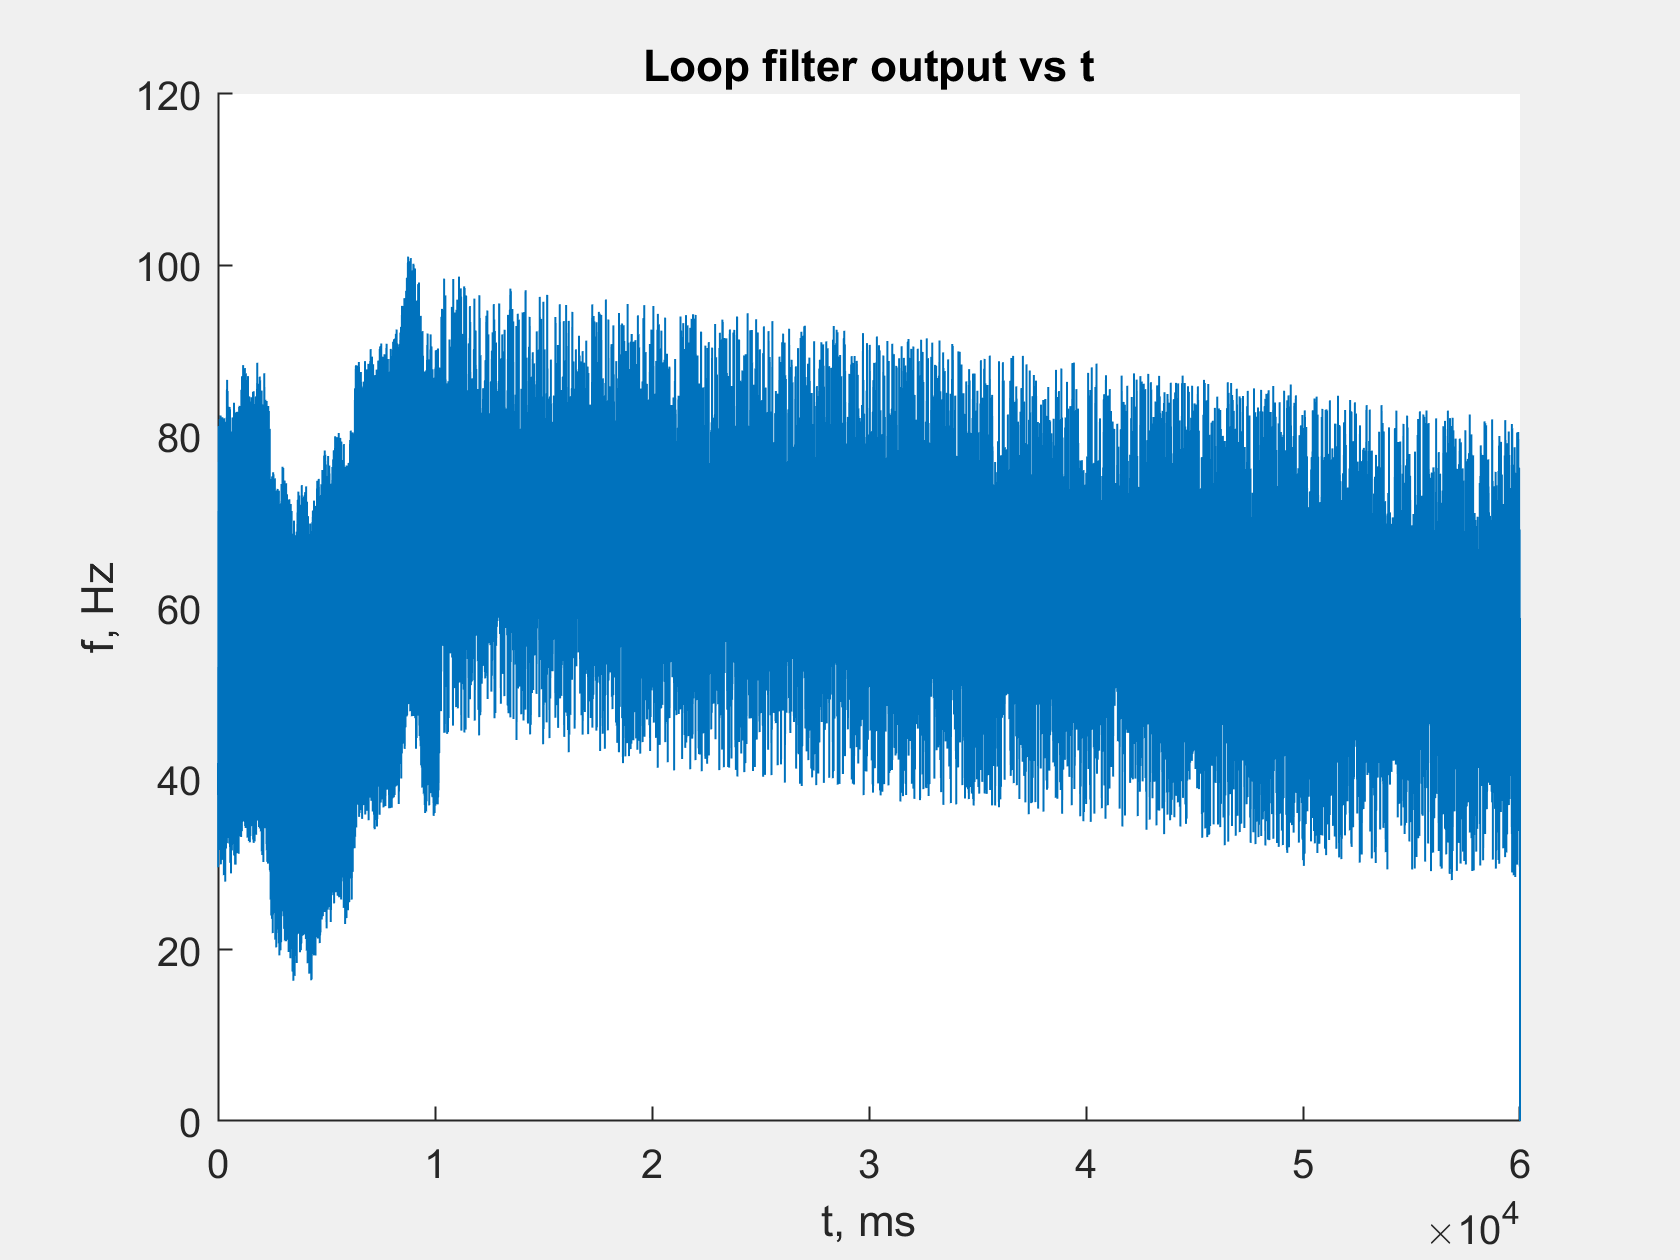

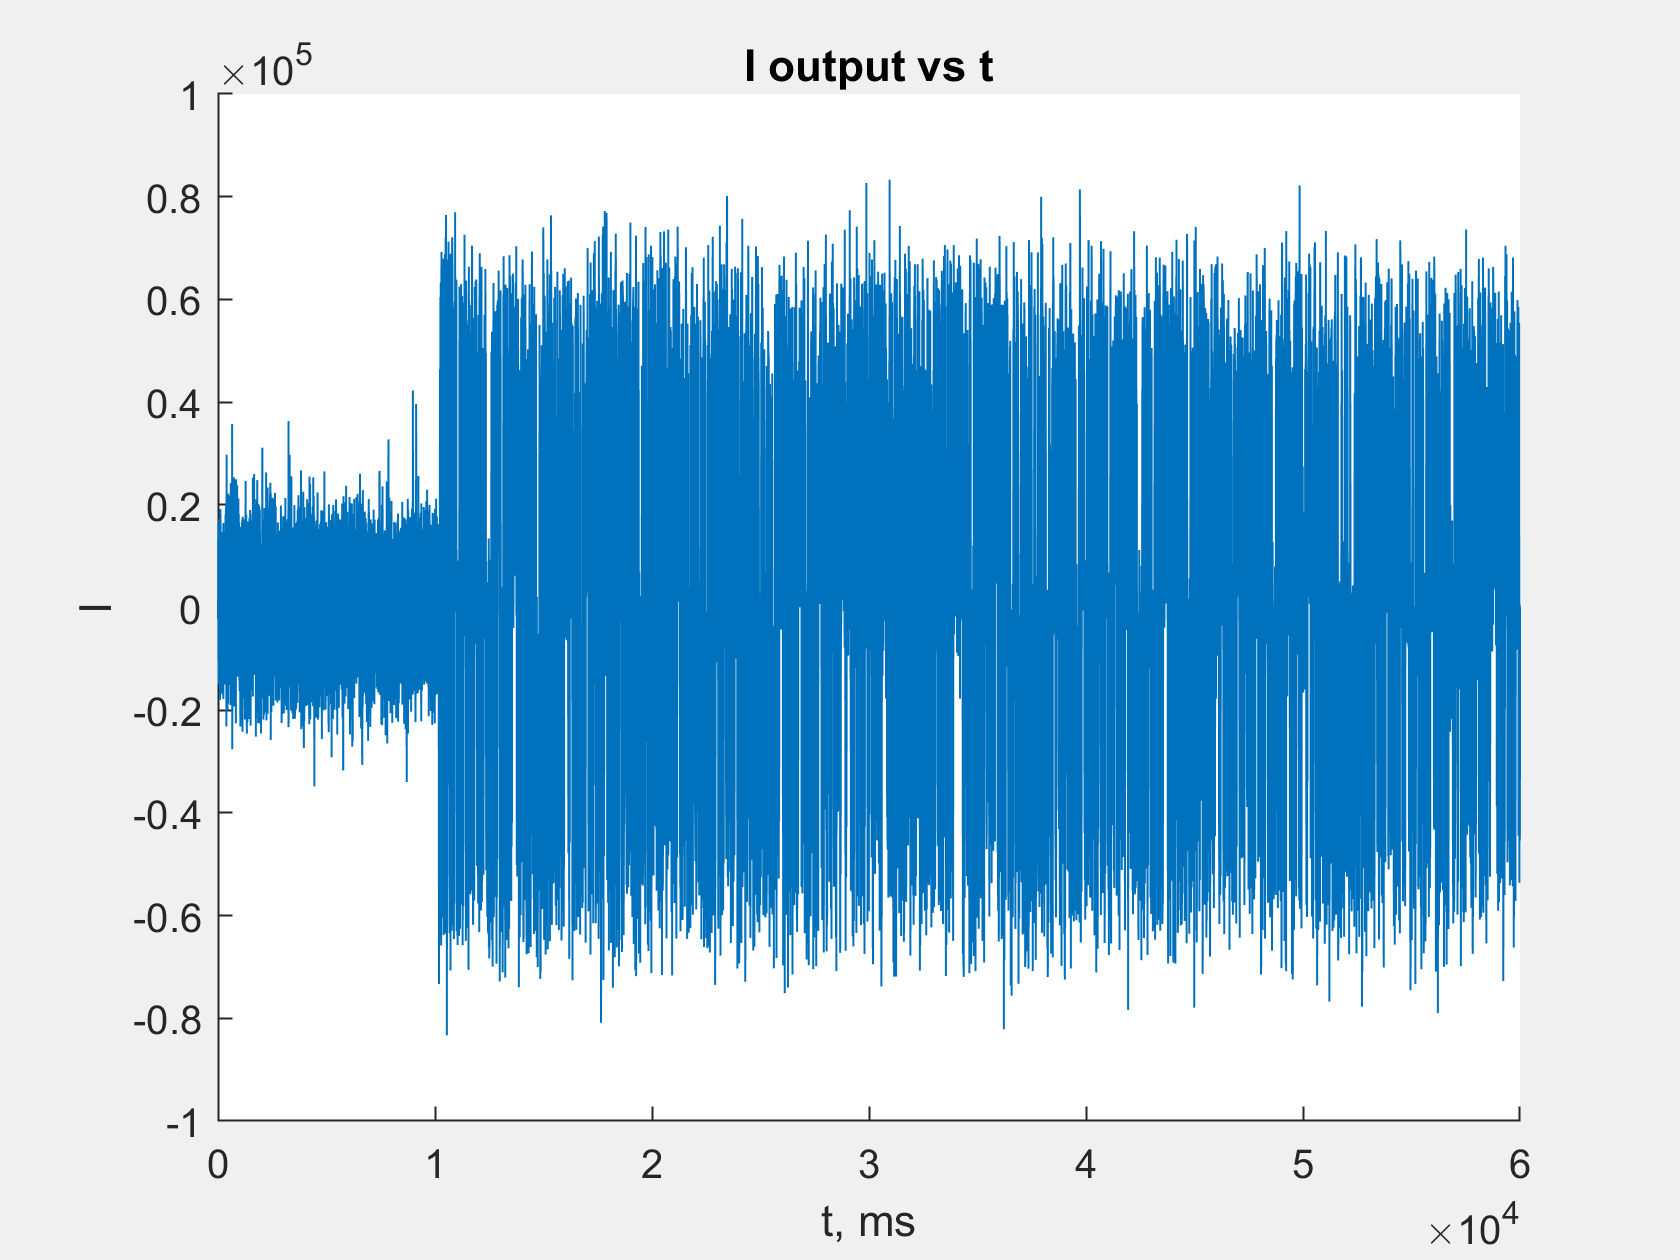

satellite_list = [30];

phi_array = load ("phi_log.mat").phi_log;
loop_filter_output_array = load ("delta_f_log.mat").delta_f_log;
I_array = load ("I_log.mat").I_log;

max_index = length (phi_array);
%max_index = 500;

phi_array = phi_array (:, 1 : max_index);
loop_filter_output_array = loop_filter_output_array (:, 1 : max_index);
I_array = I_array (:, 1 : max_index);
integrate_periods = 1;
t_values = integrate_periods * linspace (1, max_index, max_index);

for satellite_index = satellite_list
    % phi plot
    fig_phi = figure;
    set (fig_phi, 'Visible', 'on');
    hold on;
    plot (t_values, phi_array (satellite_index, :), '-');
    xlabel ('t, ms');
    ylabel ('phi, rad');
    title ('phi error from phase detector vs t');
    zoom xon;
    hold off;
    
    filename = sprintf ('phi(t)_%i.fig', satellite_index);
    savefig (fig_phi, filename);
    filename = sprintf ('phi(t)_%i.jpeg', satellite_index);
    saveas (fig_phi, filename);
    
    % Loop filter output plot
    fig_loop_filter = figure;
    set (fig_loop_filter, 'Visible', 'on');
    hold on;
    plot (t_values, loop_filter_output_array (satellite_index, :), '-');
    xlabel ('t, ms');
    ylabel ('f, Hz');
    title ('Loop filter output vs t');
    zoom xon;
    hold off;
    
    filename = sprintf ('f(t)_%i.fig', satellite_index);
    savefig (fig_loop_filter, filename);
    filename = sprintf ('f(t)_%i.jpeg', satellite_index);
    saveas (fig_loop_filter, filename);

    % I output plot
    fig_I = figure;
    set (fig_I, 'Visible', 'on');
    hold on;
    plot (t_values, I_array (satellite_index, :), '-');
    xlabel ('t, ms');
    ylabel ('I');
    title ('I output vs t');
    zoom xon;
    hold off;
    
    filename = sprintf ('I(t)_%i.fig', satellite_index);
    savefig (fig_I, filename);
    filename = sprintf ('I(t)_%i.jpeg', satellite_index);
    saveas (fig_I, filename);
end